Chapter 5_2

% Surface plot
% Data: Electricity day-ahead market price (2019)
% LMP: Local Marginal Price ($/MW)
% Day: Jan-01-2019 to Jan-07-2019
% Hour: 24 hours
clc; clear;
LMP=xlsread('surface2.xlsx')

LMP =    44.9967   56.2480   55.3468   51.2607   45.9139   44.3831   44.1278   42.1309   41.2310   40.0213   38.7816   38.4742   39.5576   42.7888   42.8066   40.7658   35.7666   29.0960   22.7794   18.9996   16.0533   14.8840   21.8590   36.8867
   44.8305   53.3640   61.9953   58.2229   52.9929   50.4424   47.1042   44.8625   43.3866   42.3716   42.2208   42.4111   43.4045   45.0377   57.9937   55.3043   42.5977   39.0772   36.4407   34.5510   31.9231   31.7445   34.6209   42.1169
   51.5220   71.3100   71.9753   62.5451   58.7773   53.8983   46.6466   42.7969   41.0990   39.7071   40.4144   39.6398   41.3517   44.0753   56.8770   50.8418   41.5099   35.9709   33.7787   31.9940   29.0733   30.5193   33.3969   40.6107
   49.8493   69.3141   71.0427   60.6604   57.1362   50.6729   44.8080   41.3024   40.1341   38.8131   38.8424   39.5107   40.0722   43.5883   55.3317   48.5251   40.6936   34.6420   33.1419   32.2070   30.7925   31.0946   32.3366   37.5603
   50.0476   68.4420   67.1451

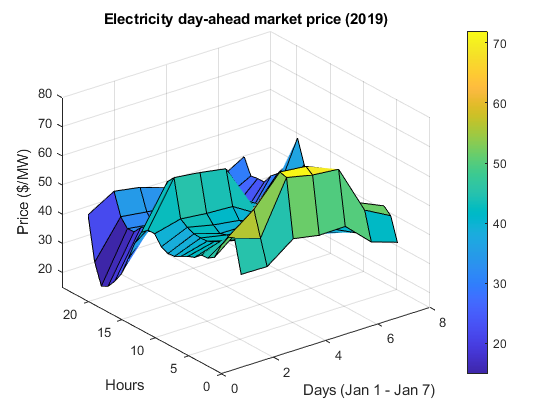

Day=1:7;
Hour=1:24;
[DAY,HOUR]=meshgrid(Day,Hour);
surf(DAY,HOUR,LMP')
colorbar
xlabel('Days (Jan 1 - Jan 7)');
ylabel('Hours');
zlabel('Price ($/MW)');
title('Electricity day-ahead market price (2019)');